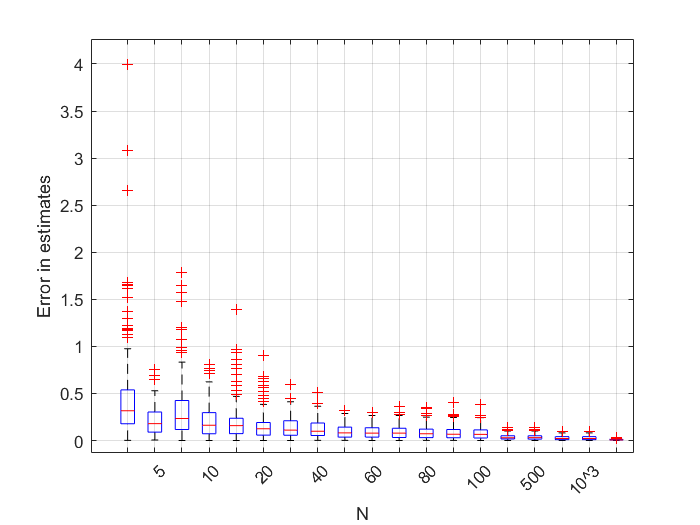

rng(1);

%declaring the size of each data set 
W = [5 10 20 40 60 80 100 500 10^3 10^4];
%declaring teh error matrix with one row and no of columns as the size of
%the data entries for which the error is to be calcuated 
error = zeros(200,2 * length(W),"double");
%declared a global iterative variable 
k = 1;

for N = W 
  for w = 1:200  
    sample = [N 1];
    %to have the dimension of the data set intialized to a vector 
    %generating a data set of N entries 
    sample1 = rand(sample);%generating a random uniform distribution between 0,1
    %putting up the variables given in question
    %gneration of the data 
    lambda = 5;
    alpha = 5.5;
    beta = 1;
    for v = 1:N
      sample1(v) = -log(sample1(v)) / lambda; %transformation of the random variable 
    end
    % AS described in the report the maximum likelihood funciton when
    % calculated by mulitplying all the distribution for each x we get the
    % final out put 
    lambda_mle = N / sum(sample1);
    %once again every therory is explained in the report here calculated the
    %bayesian estimate of lamda and the final output is 
    lambda_bay = (N + alpha) / (sum(sample1) + beta);
    %storing the error value for each iteration w for each dataset in
    %columns   
    error(w,2 * k - 1) = abs(lambda - lambda_mle) / lambda;
    error(w,2 * k) = abs(lambda - lambda_bay) / lambda;
  end
    k = k + 1;
end 

figure;
axis equal;
boxplot(error, 'Labels', {'','5','','10','','20','','40','','60','','80','','100','','500','','10^3','','10^4'});
xlabel("N");
ylabel("Error in estimates");
grid on